# System identification of mars rover drive chain

## Generate input data


h = 0.01; % Sampling period
uu = idinput(6000, 'rbs', [0, 0.8]);
currentMagnitude = 1e-2;
u1 = currentMagnitude*uu(1:3000);
u1v = currentMagnitude*uu(3001:6000);
t = (0:2999)'*h;
input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);


## Load simulation results

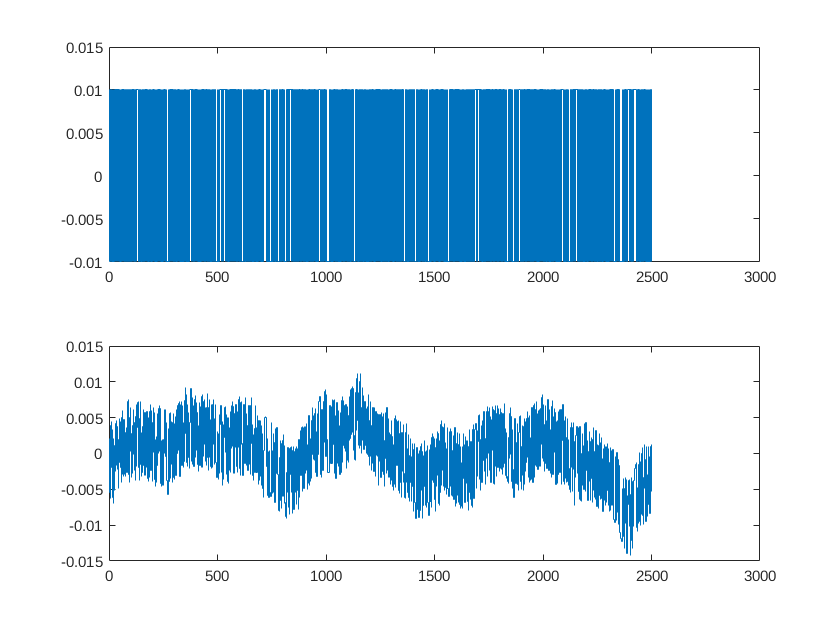

load rover-sysid.mat
skipfirst=500; % Skip first five seconds
% Remove mean
uident = detrend(out.Data(skipfirst:end,1), 0);
yident = detrend(out.Data(skipfirst:end,2), 0);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

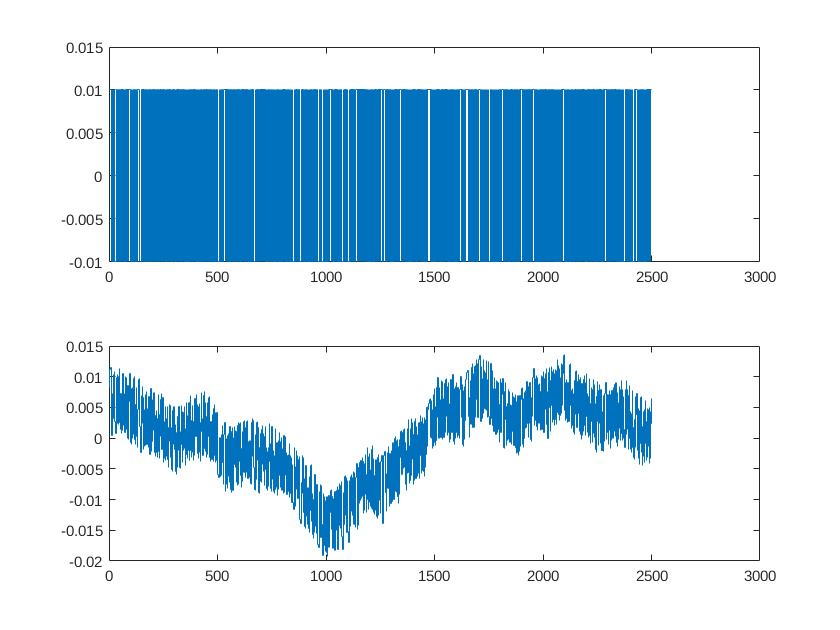


load rover-sysid-val.mat
uval = detrend(out.Data(skipfirst:end,1), 0);
yval = detrend(out.Data(skipfirst:end,2), 0);

figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)